# Segmentació de la imatge

## Watershed

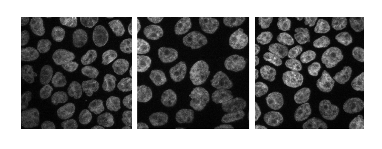

I = rgb2gray(imread("cellsegmentationcompetition.png"));
imshow(I);

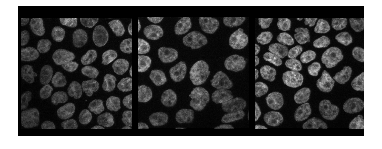

% eliminar marcs
IB = I > 250;
SB = false(size(I));
SB(:,1) = true;
SB(:,end) = true;
SB(1,:) = true;
SB(end,:) = true;
RB = imreconstruct(SB,IB);
RB = imdilate(RB,ones(6,6));
I(RB) = 0;
imshow(I);

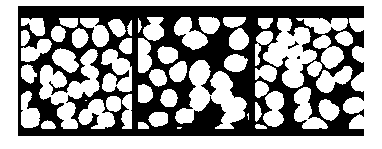

% preprocesat (filtrat)
OI = imopen(I, strel('disk',4));
CI = imclose(OI, strel('disk',4));
BW = CI > 16;
imshow(BW);

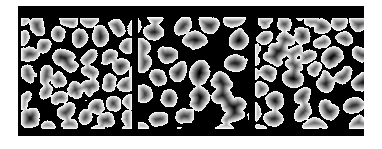

% segmentació per watershed
DT = -bwdist(not(BW)); % transformada de distància
DT(not(BW)) = -Inf; % no aplicar watershed al background
DT = imclose(DT, strel('disk',4)); % eliminem pous petits
imshow(DT,[]);

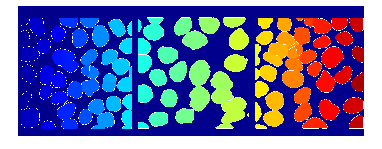

L = watershed(DT);
imshow(label2rgb(L));

## Exercici: segmentar

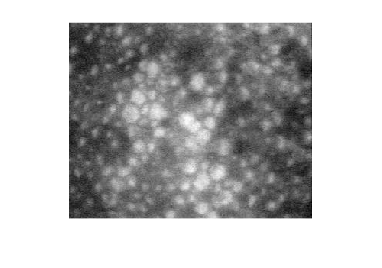

I = imread('cornea.tif');
imshow(I);

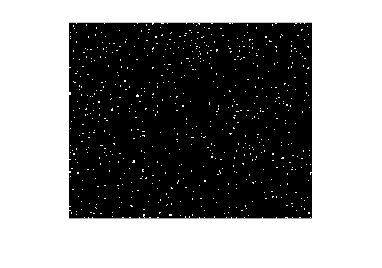

% Màxims regionals
I = medfilt2(I, [3, 3]);
MARK_C = imregionalmax(I);
imshow(MARK_C);

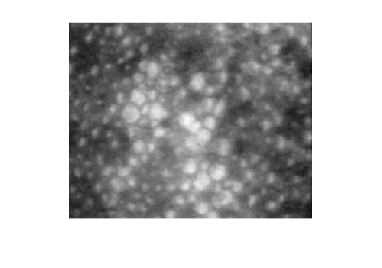

% imatge reconstruccio
IREC = imreconstruct(I.*uint8(MARK_C),I);
imshow(IREC);

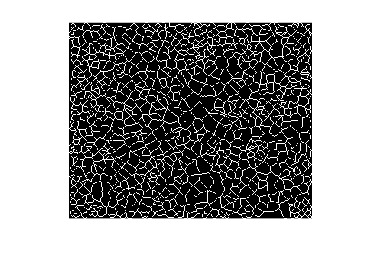

% SKIZ
SK = bwskel(not(MARK_C));
MARK_B = bwmorph(SK,'spur',Inf);
MARK_B = MARK_B & not(bwhitmiss(MARK_B,[-1,-1,-1;-1,1,-1;-1,-1,-1]));
imshow(MARK_B);

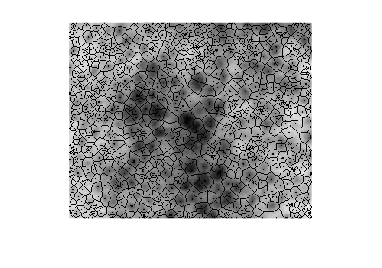

% Imatge de marques
MARKERS = (255-I) .* uint8(not(MARK_B)) .* uint8(not(MARK_C));
imshow(MARKERS);

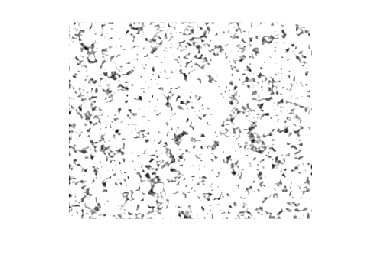

% Imatge gradient
G = uint8(imgradient(IREC));
G = imfilter(G, ones(3,3));
imshow(G,[]);

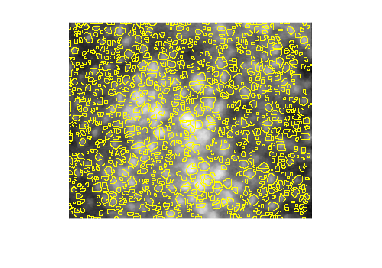

% watershed
WS = watershed(double(G).*double(MARKERS));
IB = WS == 0;
RGB = imoverlay(I, IB);
imshow(RGB);

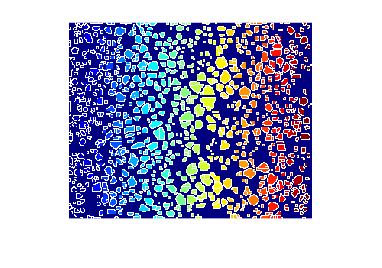

imshow(label2rgb(WS));

## K-Means

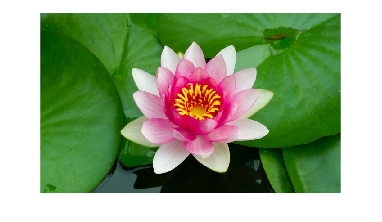

% reduir el nombre de colors d'una imatge
I = imread("nenufar.jpg");
imshow(I);

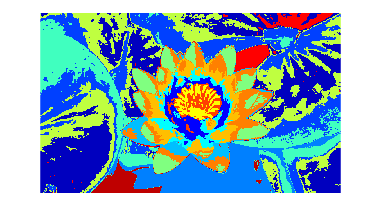

R = I(:,:,1);
G = I(:,:,2);
B = I(:,:,3);
O = [R(:),G(:),B(:)];
[C Cen] = kmeans(double(O), 15);
[f c p] = size(I);
C = reshape(C,[f c]);
imshow(label2rgb(C));